# Create Custom Messages from ROS 2 Package

Use custom messages to extend the set of message types currently supported in ROS 2. Custom messages are messages that you define. If you are sending and receiving supported message types, you do not need to use custom messages. To see a list of supported message types, enter `ros2 msg list` in the MATLAB® Command Window. For more information about supported ROS 2 messages, see [Work with Basic ROS 2 Messages](docid:ros_ug#mw_8a48f84f-f79b-4aa6-8163-a8ef53743751).

If this if your first time working with ROS 2 custom messages, see [ROS System Requirements](docid:ros_gs#mw_73c6a0b7-7d2c-486e-b968-900d6af4f1fa).

ROS 2 custom messages are specified in ROS 2 package folders that contain a folder named `msg`. The `msg` folder contains all your custom message type definitions. For example, the `example_b_msgs `package in the `custom` folder, has this folder and file structure.

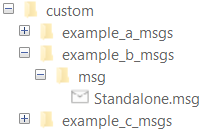

The package contains the custom message type `Standalone.msg`. MATLAB uses these files to generate the necessary files for using the custom messages contained in the package.

In this example, you create ROS 2 custom messages in MATLAB. You must have a ROS 2 package that contains the required `msg` file.

After ensuring that your custom message package is correct, you specify the path to the parent folder and call `ros2genmsg` with the specified path. The following example provided three messages `example_package_a,` `example_package_b`, and `example_package_c` that have dependencies. This example also illustrates that you can use a folder containing multiple messages and generate them all at the same time.

Specify the folder path for custom message files and use `ros2genmsg` to create custom messages.

ros2genmsg(fileparts(matlab.desktop.editor.getActiveFilename))

Call `ros2 msg list` to verify creation of new custom messages.

ros2 msg list

You can now use the above created custom message as the standard messages. For more information on sending and receiving messages, see [Exchange Data with ROS 2 Publishers and Subscribers](docid:ros_ug#mw_56920b2c-f2f6-4d6c-a7d6-97877266558d).

Create a publisher to use `example_b_msgs/Standalone` message.

node = ros2node("/node_1");
pub = ros2publisher(node,"/example_topic","example_b_msgs/Standalone");

Create a subscriber on the same topic.

sub = ros2subscriber(node,"/example_topic");

Create a message and send the message.

custom_msg = ros2message("example_b_msgs/Standalone");
custom_msg.int_property = uint32(12);
custom_msg.string_property='This is ROS 2 custom message example';
send(pub,custom_msg);
pause(1) % Allow a few seconds for the message to arrive

Use `LatestMessage` field to know the recent message received by the subscriber.

sub.LatestMessage

Remove the created ROS objects.

clear node pub sub

### Replacing Definitions of Built-In Messages with Custom Definitions

MATLAB provides a lot of built-in ROS 2 message types. You can replace the definitions of those message types with new definitions using the same custom message creation workflow detailed above. When you are replacing the definitions of a built-in message package, you must ensure that the custom message package folder contains new definitions (`.msg` files) for all the message types in the corresponding built-in message package.

*Copyright 2019-2020 The MathWorks, Inc.*